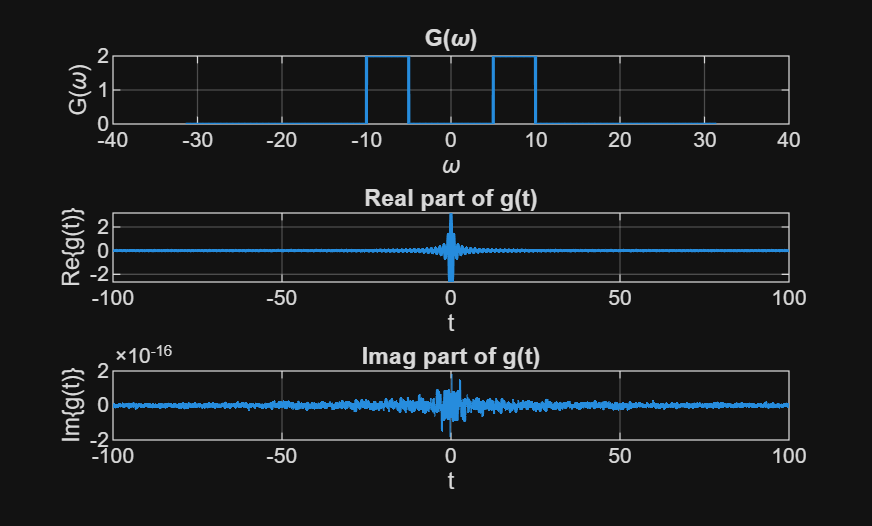

% 1.
% Grids
omega = -31.4:0.01:31.4; % frequency axis
t = -100:0.1:100; % time axis

% (a): G(ω) and g(t)
% G(ω) = 2 for 5 <= |ω| <= 10, else 0
G = 2 .* ( (abs(omega) >= 5) & (abs(omega) <= 10) );
% Inverse FT: g(t) = (1/2π) ∫ G(ω) e^{j ω t} dω
% Use numerical integration with trapz over ω
E = exp(1j * (omega(:) .* t)); % [Nω x Nt]
F = (G(:) .* ones(size(t))) .* E; % broadcast G over t
g = (1/(2*pi)) * trapz(omega, F, 1); % integrate along ω  -> 1xNt

% Plot G(ω), Re{g(t)}, Im{g(t)}
figure('Name','Part (a)');
subplot(3,1,1);
plot(omega, G, 'LineWidth', 1.2);
xlabel('\omega'); ylabel('G(\omega)'); grid on; title('G(\omega)');
subplot(3,1,2);
plot(t, real(g), 'LineWidth', 1.2);
xlabel('t'); ylabel('Re\{g(t)\}'); grid on; title('Real part of g(t)');
subplot(3,1,3);
plot(t, imag(g), 'LineWidth', 1.2);
xlabel('t'); ylabel('Im\{g(t)\}'); grid on; title('Imag part of g(t)');

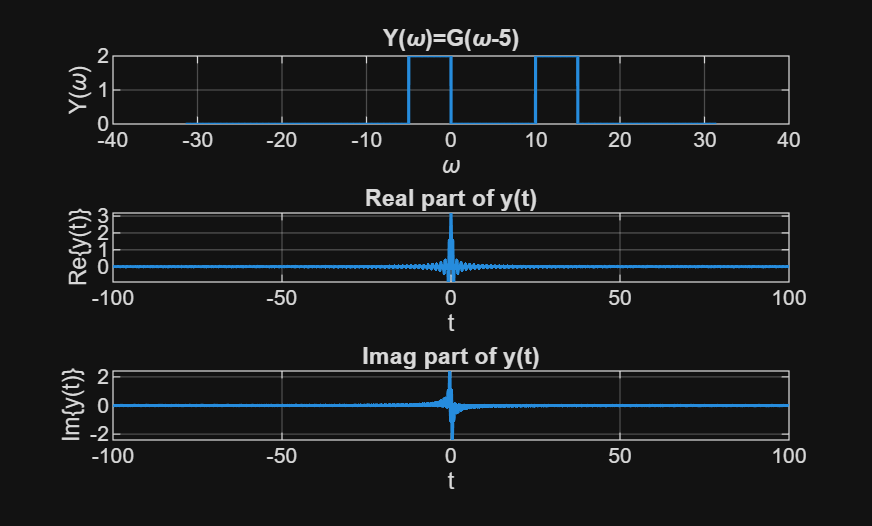


% (b): Y(ω) = G(ω - 5) and y(t)
Y = 2 .* ( (abs(omega - 5) >= 5) & (abs(omega - 5) <= 10) );
% Two equivalent ways to get y(t):
% (1) Numerically from inverse FT of Y(ω):
E2 = exp(1j * (omega(:) .* t));
F2 = (Y(:) .* ones(size(t))) .* E2;
y_num = (1/(2*pi)) * trapz(omega, F2, 1);
% (2) Property: frequency shift -> time modulation
% Y(ω)=G(ω-5)  ==>  y(t) = g(t) * e^{j*5t}
y_prop = g .* exp(1j*5*t);
% Use the property version (identical to y_num up to numerical error)
y = y_prop;

% Plot Y(ω), Re{y(t)}, Im{y(t)}
figure('Name','Part (b)');
subplot(3,1,1);
plot(omega, Y, 'LineWidth', 1.2);
xlabel('\omega'); ylabel('Y(\omega)'); grid on; title('Y(\omega)=G(\omega-5)');
subplot(3,1,2);
plot(t, real(y), 'LineWidth', 1.2);
xlabel('t'); ylabel('Re\{y(t)\}'); grid on; title('Real part of y(t)');
subplot(3,1,3);
plot(t, imag(y), 'LineWidth', 1.2);
xlabel('t'); ylabel('Im\{y(t)\}'); grid on; title('Imag part of y(t)');


% (c): Real vs Complex
% g(t) is real (G is real and even), so imag(g) ≈ 0 (numerical noise).
% y(t) = g(t) e^{j5t} is generally complex (nonzero imag and real parts).


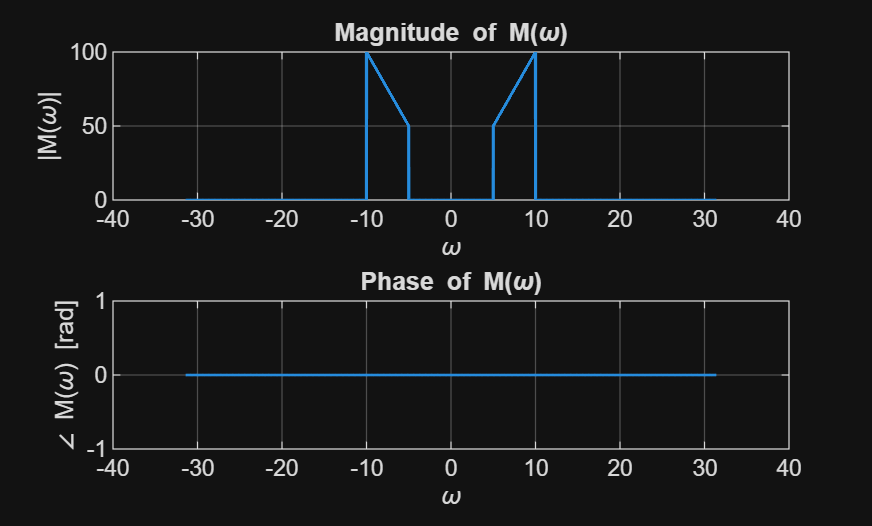

% 2. 
% Grids
omega = -31.4:0.01:31.4;
t = -100:0.1:100;
% G(ω) from Problem 1 
G = 2 .* ( (abs(omega) >= 5) & (abs(omega) <= 10) );
% Inverse FT of G to get g(t) 
E = exp(1j * (omega(:) .* t)); % [Nω x Nt]
g = (1/(2*pi)) * trapz(omega, (G(:).*ones(size(t))).*E, 1);
% Filtering with H(ω)
% H(ω) = 5|ω| for |ω| ≤ 20, else 0
H = 5*abs(omega) .* (abs(omega) <= 20);

% (a) Convolution theorem -> multiply spectra
M = G .* H;

% Plot |M(ω)| and ∠M(ω)
figure('Name','Problem 2(a): M(\omega)');
subplot(2,1,1);
plot(omega, abs(M), 'LineWidth', 1.2); grid on;
xlabel('\omega'); ylabel('|M(\omega)|'); title('Magnitude of M(\omega)');
subplot(2,1,2);
plot(omega, angle(M), 'LineWidth', 1.2); grid on;
xlabel('\omega'); ylabel('\angle M(\omega) [rad]'); title('Phase of M(\omega)');

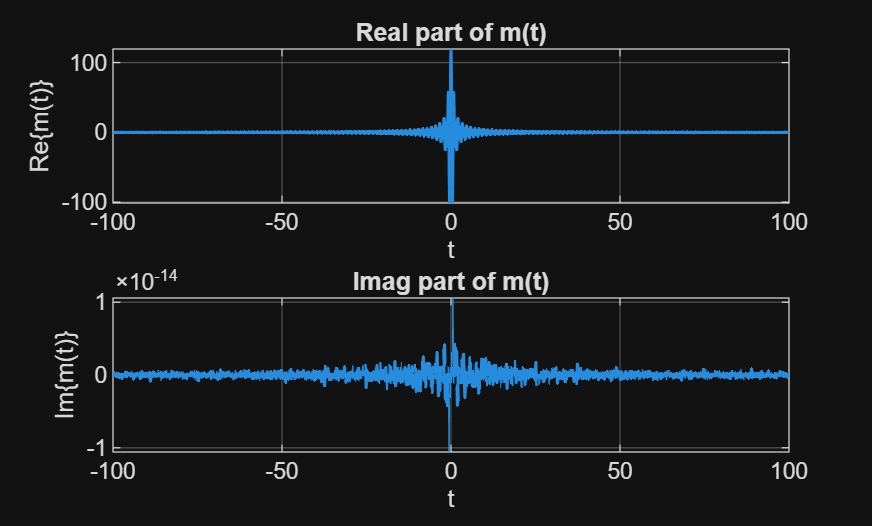


% (b) m(t) via inverse FT of M(ω)
E2 = exp(1j * (omega(:) .* t));
m = (1/(2*pi)) * trapz(omega, (M(:).*ones(size(t))).*E2, 1);
figure('Name','Problem 2(b): m(t)');
subplot(2,1,1);
plot(t, real(m), 'LineWidth', 1.2); grid on;
xlabel('t'); ylabel('Re\{m(t)\}'); title('Real part of m(t)');
subplot(2,1,2);
plot(t, imag(m), 'LineWidth', 1.2); grid on;
xlabel('t'); ylabel('Im\{m(t)\}'); title('Imag part of m(t)');

% 3. 
% Grids
omega = -31.4:0.01:31.4; % frequency axis
t = -100:0.1:100; % time axis
domega = omega(2)-omega(1);
dt = t(2)-t(1);
% Rebuild M(ω) via G(ω) and H(ω) (so this cell is standalone)
G = 2 .* ( (abs(omega) >= 5) & (abs(omega) <= 10) ); % from Q1
H = 5*abs(omega) .* (abs(omega) <= 20); % from Q2
M = G .* H;
% m(t) via inverse FT of M(ω)
E = exp(1j * (omega(:) .* t));
m = (1/(2*pi)) * trapz(omega, (M(:).*ones(size(t))).*E, 1);
% Energy in time domain
E_time = trapz(t, abs(m).^2);
%%Energy in frequency domain (Parseval)
E_freq = (1/(2*pi)) * trapz(omega, abs(M).^2);
% Report
fprintf('Energy (time domain)     : %.6g\n', E_time);

Energy (time domain)     : 9284.38


fprintf('Energy (frequency domain): %.6g\n', E_freq);

Energy (frequency domain): 9295.98


fprintf('Absolute difference      : %.3e\n', abs(E_time - E_freq));

Absolute difference      : 1.160e+01
